# **Second Optimal Control Project**

# **Designing a Continues Infinite-Time LQR for a Linear 1/4-Car System**

## Ali Eidizadeh                            ali80ei@gmail.com

## Amirhadi Keyvan     amirhadikeyvan@gmail.com

clear all;
close all;
clc

% System definition
A = [0 1 0 0;
     0 -0.14 -32 0.14;
     0 1 0 -1;
    -1562.5 1.0937 1812.5 -48.0312];

B = [0;
     0.0004;
     0;
    -0.0031];

C = [1 0 0 0;
     0 1 0 0;
     0 0 1 0];
D = zeros(size(C, 1), size(B, 2));

Q = C'*C;
R = 1;
X0 = [0.2; 0.2; 0.2; 0.2];

rank(obsv(sqrt(Q),A))

ans = 4

rank(ctrb(A,B))

ans = 4

F1=lqr(A,B,Q,R);

Ks2=care(A,B,Q,R);
F2=-inv(R)*B'*Ks2;

M=[A -B*inv(R)*B';-Q -A'];
[V,E]=eig(M);
c=0;
n=max(size(A));
for i=1:1:2*n
if real(E(i,i))<0
c=c+1;
V1(:,c)=V(:,i);
end
end
Ks3=V1(n+1:2*n,:)*inv(V1(1:n,:));
Ks3=real(Ks3);
F3=-inv(R)*B'*Ks3;

Q = C'*C;
R = 1;
X0 = [0.2; 0.2; 0.2; 0.2];
T_final = 60;
Ts = 0.01;
t = 0:Ts:T_final;
N = length(t);

T_final = 60;
Ts = 0.01;
t = 0:Ts:T_final;

F_list = {F1, F2, F3};
labels = {'F1 (lqr)', 'F2 (care)', 'F3 (Hamiltonian)'};

x_all = cell(1,3);
u_all = cell(1,3);

for i = 1:3
    F = F_list{i};

    % Define dynamics for ode45
    u_func = @(x) -F * x;
    dxdt = @(t, x) A*x + B*u_func(x);

    % Simulate
    [T, X] = ode45(dxdt, t, X0);

    % Evaluate control input
    U = zeros(length(T), 1);
    for j = 1:length(T)
        U(j) = u_func(X(j,:)');
    end

    x_all{i} = X';
    u_all{i} = U';
end


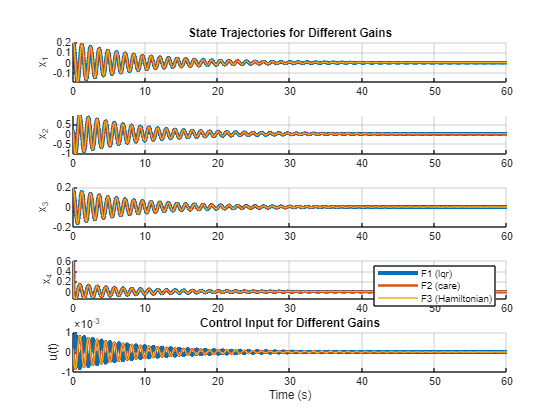

lineWidths = [3, 2, 1];  
labels = {'F1 (lqr)', 'F2 (care)', 'F3 (Hamiltonian)'};

figure;

% Plot each state x1 to x4
for idx = 1:4
    subplot(5,1,idx); hold on;
    for i = 1:3
        plot(t, x_all{i}(idx,:), 'LineWidth', lineWidths(i));
    end
    ylabel(['x_' num2str(idx)]);
    grid on;
    if idx == 1
        title('State Trajectories for Different Gains');
    end
end

% Legend once
legend(labels);

% Plot input u
subplot(5,1,5); hold on;
for i = 1:3
    plot(t, u_all{i}, 'LineWidth', lineWidths(i));
end
xlabel('Time (s)');
ylabel('u(t)');
title('Control Input for Different Gains');
grid on;